# Exemple pentru metoda lui Newton

## Prezentarea metodei

Dorim să rezolvăm ecuația $f(x)=0$. 

Metoda: se pornește cu un $x_0$ dat și se execută pasul iterativ


$$x_{k+1}=x_k-\frac{f\left( x_k \right)}{f'\left( x_k \right)}$$


până când $\vert x_{k+1}- x_k \vert<\varepsilon$, $\varepsilon$ precizie dată.

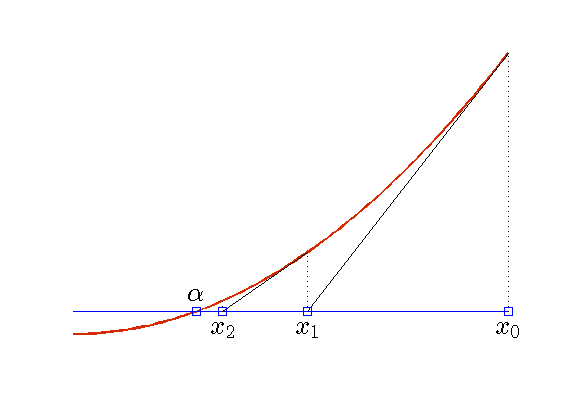

Vom implementa o variantă a metodei care să funcționeze și pentru sisteme de ecuații neliniare. Pentru un sistem metoda lui Newton are forma


$$x^{\left(k+1\right)} =x^{\left(k\right)} -{\left\lbrack f^{\prime } \left(x^{\left(k\right)} \right)\right\rbrack }^{-1} f\left(x^{\left(k\right)} \right)\ldotp$$


În acest caz derivata $f'\left( x^{(k)}\right)$ este matricea jacobiană în $x^{(k)}$. *Inversarea de matrice este o operație costisitoare și generatoare de erori și de aceea trebuie evitată*. Iterația se poate scrie sub forma $x^{\left(k+1\right)} =x^{\left(k\right)} -w^{\left(k\right)} \ldotp$ Corecția $w^{(k)}$ se poate obtine ca soluție a sistemului


$$f^{\prime } \left(x^{\left(k\right)} \right)w^{\left(k\right)} =f\left(x^{\left(k\right)} \right)\ldotp$$


Rezolvarea se poate realiza în MATLAB cu operatorul \.

O condiție suficientă de convergență este $f\left(x_0 \right)f''\left(x_0 \right)>0$.

## Exemplu: o ecuație scalară

Polinomul $x^3-2x-5$ a fost utilizat de Wallis pentru a prezenta metoda lui Newton în fața Academiei franceze. Să definim polinomul și derivata sa.

f=@(x) x.^3-2*x-5;
fd = @(x) 3*x.^2-2;

Reprezentăm grafic polinomul:

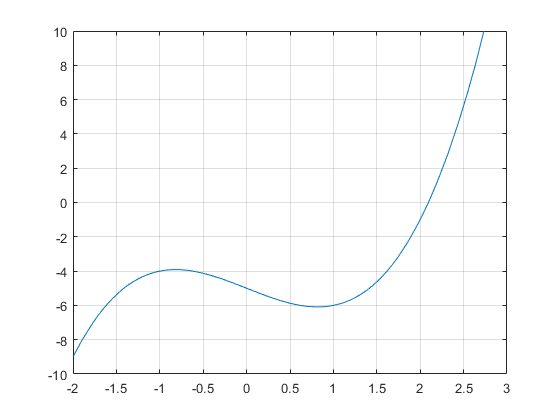

fplot(f, [-2,3])
ylim([-10,10])
grid on

El are o rădăcină reală între $x=2$ și $x=3$ și o pereche de rădăcini complexe conjugate, cum se poate verifica

f(2)

ans = -1

f(3)

ans = 16

Determinăm rădăcina reală cu metoda lui Newton. Alegem valoarea de pornire $x_0=3$ și precizia $\varepsilon=10^{-8}$

x0=3;
[z1,ni1] = Newton(f,fd,x0, 1e-8)

z1 = 2.0946

ni1 = 6

Precizia dorită a fost obținută dupa 6 iterații. Pentru determinarea rădăcinilor complexe vom utiliza valori de pornire complexe.

x0=1i;
[z2,ni2] = Newton(f,fd,x0, 1e-8)

z2 = -1.0473 + 1.1359i

ni2 = 8

Verificăm soluțiile

f([z1,z2,conj(z2)])

ans = 	1.0e+-15 *

  -0.8882 + 0.0000i   0.0000 - 0.8882i   0.0000 + 0.8882i


## Aplicație la calculul radicalului

Vom folosi metoda lui Newton pentru a calcula $\sqrt{a}$, $a>0$. Pornim de la ecuația $f(x)=x^2-a=0$. Iterația Newton devine


$$x_{n+1} =x_n -\frac{x_n^2 -a}{2x_n }=\frac{x_n^2 +a}{2x_n }=\frac{1}{2}\left(x_n +\frac{a}{x_n }\right)$$


Ținând cont că $f$ este convexă, putem alege ca valoare de pornire orice $x_0$ pentru care $f(x_0)>0$, adică $x_0 \geq \sqrt{a}$. O alegere potrivită este sugerată de inegalitatea mediilor

$\sqrt{a}=\sqrt{a\cdot 1}\leq \frac{a+1}{2}$,

deci, vom lua $x_0=\frac{a+1}{2}$. Șirul astfel obținut este descrescător și marginit inferior de $\sqrt{a}$, deci convergent.

Vom obține un *algoritm independent de mașină, care exploatează aritmetica finită*. Ținând cont că într-un interval mărginit avem un număr finit de numere în virgulă flotantă, vom termina iterațiile când $x_{n+1}\geq x_{n}$. Dăm codul pentru această funcție

De menționat că în aritmetica exactă acest algoritm ciclează la infinit. 

Să dăm două exemple de utilizare:

Sqrt(2)

ans = 1.4142

Sqrt(11)

ans = 3.3166

## O ecuație transcendentă

Considerăm ecuația $h(x)=e^x+1+x=0$. Această ecuație se poate rezolva doar numeric. Să reprezentăm grafic funcția

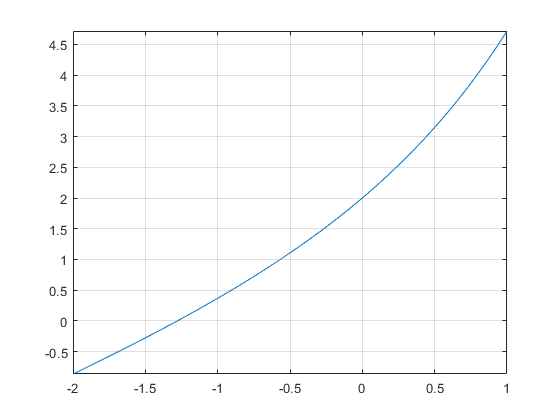

h=@(x) exp(x)+x+1; %functia
hd = @(x) exp(x)+1;
fplot(h,[-2,1])
grid on

h(-2)

ans = -0.8647

h(1)

ans = 4.7183

Deoarece $h(-2)<0$ și $h(1)>0$, funcția $h$ are o rădăcină în intervalul $[-2,1]$. Vom alege valoarea de pornire $x_0=1$ și precizia $\varepsilon=10^{-4}$

[z,ni]=Newton(h,hd,1,1e-4)

z = -1.2785

ni = 5

## Cicluri în metoda lui Newton

Metoda lui Newton poate intra într-un ciclu infinit. Iterația 


$$x_{n+1} =x_n -\frac{f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$


poate cicla la stânga și la dreapta unui punct $a$ dacă


$$x_{n+1} -a=-\left(x_n -a\right)\ldotp$$


Aceasta se întampla dacă $f$ satisface


$$x-a-\frac{f\left(x\right)}{f^{\prime } \left(x\right)}=-\left(x-a\right)\ldotp$$


Aceasta este o ecuație diferențială cu variabile separabile


$$\frac{f^{\prime } \left(x\right)}{f\left(x\right)}=\frac{1}{2\left(x-a\right)},$$


cu soluția $f(x)=sign(x-a)\sqrt{\vert x-a \vert}$. Rădăcina lui $f(x)$ este $x^{*}=a$. Graficul lui $f$, pentru $a=2$, se poate obține cu

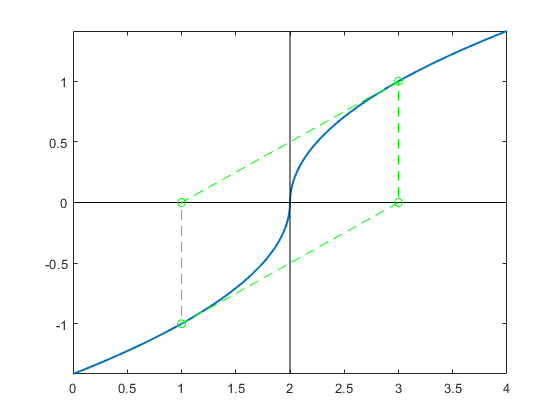

syms t
f=@(x) sign(x-2).*sqrt(abs(x-2));
hg=fplot(f,[0,4]); hold on
hg.LineWidth=1.5;
plot([0,4],[0,0],'k-',[2,2],[f(0),f(4)],'k-')
xx=[3,1,1,3,3];
plot(xx,[f(3),0,f(1),0,f(3)],'g--o'); 
hold off

Dacă desenăm tangenta la grafic în orice punct, ea va intersecta axa $Ox$ în simetricul lui $[a,0]$ față de $Oy$. Metoda lui Newton ciclează la infinit între valorile $x_0$ și $x_1$. Teoria convergenței pentru metoda lui Newton nu funcționează, deoarece derivata este infinită în $x=a$.

fd = matlabFunction(2*abs(t - 2)^(1/2)*dirac(t - 2) +... 
    sign(t - 2)^2/(2*abs(t - 2)^(1/2)),'Vars',t);
try
z = Newtondbg(f,fd,3,1e-4,0,6)
catch
    disp('ciclu');
end

x_{ 1}=1.000000
x_{ 2}=3.000000
x_{ 3}=1.000000
x_{ 4}=3.000000
x_{ 5}=1.000000
x_{ 6}=3.000000


ciclu


Un alt exemplu: Aplicați metoda lui Newton ecuației $g(x)=4x^4-6x^2-\frac{11}{4}$ cu valoarea de pornire $x_0=\frac{1}{2}$. 

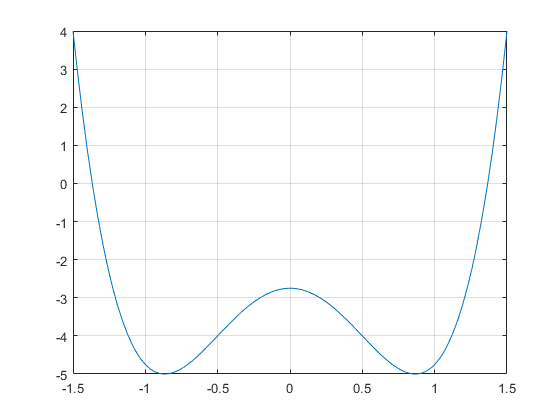

g = @(x) 4*x.^4-6*x.^2-11/4;
dg = @(x) 16*x.^3-12*x;
fplot(g,[-1.5,1.5])
grid on

Și în acest caz metoda lui Newton ciclează.

try
z = Newtondbg(g,dg,1/2,1e-4,0,6)
catch
    disp('ciclu');
end

x_{ 1}=-0.500000
x_{ 2}=0.500000
x_{ 3}=-0.500000
x_{ 4}=0.500000
x_{ 5}=-0.500000
x_{ 6}=0.500000


ciclu


## Divergența

Șirul aproximantelor ar putea să nu convergă. Aplicăm metoda lui Newton ecuației $u(x)=x^\frac{1}{3}=0$, cu valoarea de pornire $x_{0}=1$.

u = @(x) x.^(1/3);
du = @(x) 1/3*x.^(-2/3);
x0=1;
try
    [z,ni] = Newton(u,du,x0,1e-3,0,100);
    ni
catch ME
    disp('metoda nu converge, nit=%d\n')
end

metoda nu converge, nit=%d\n


În acest caz șirul iterațiilor devine


$$x_{n+1} =x_n -\frac{x_n^{\frac{1}{3}} }{\frac{1}{3}x_n^{-\frac{2}{3}} }=x_n -3x_n =2x_n ,$$


care este nemărginit.

## Comportare haotică

- Determinați o rădăcină a funcției $f(x)=\left( 1-\frac{3}{4x}\right)^\frac{1}{3}$. 

- Aplicați metoda lui Newton alegând o valoare de pornire în vecinatatea rădăcinii și reprezentați primele 50 de iterații. Acesta este un alt mod în care metoda lui Newton poate eșua, producând o traiectorie haotică.

- De ce nu se poate aplica teoria referitoare la convergența metodei lui Newton?

f = @(x) nthroot(1-3./(4*x),3)

f = function_handle with value:
    @(x)nthroot(1-3./(4*x),3)


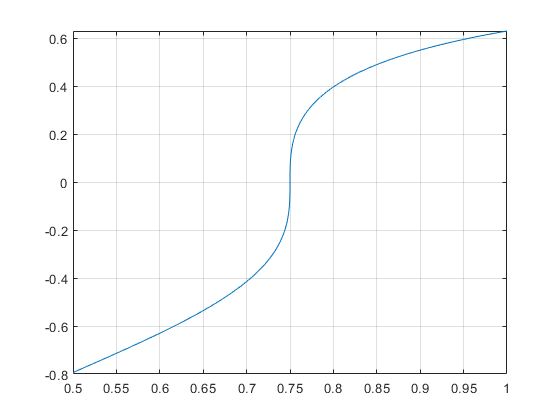

df = @(t) -nthroot(1 - 3./(4*t), 3)./(4*t.^2*(3./(4*t) - 1));
fplot(f,[0.5,1])
grid on

O rădăcina este $x^{*}=\frac{3}{4}$.

x0 = 0.749;
[z,ni]=Newtonvect(f,df,x0,1e-4,0,50);

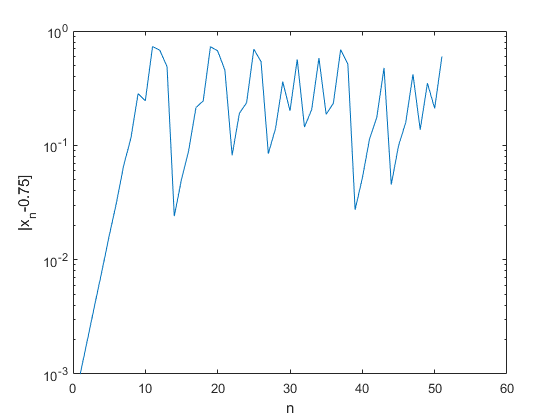

semilogy(abs(z-0.75))
xlabel('n')
ylabel('|x_n-0.75]')

Funcția `Newtonvect` este o variantă de implementare care păstrează toate aproximantele. Este utilă pentru a ilustra comportamentul metodei.

## Metoda lui Newton nu converge neapărat către cea mai apropiată rădăcină

Considerăm ecuația $p(x)=x^4-x^2=0$. Ea are trei rădăcini: 0 (dublă), 1 și -1. Alegem $x_0=-0.7$. Cea mai apropiată rădăcina este -1, dar metoda lui Newton va converge către rădăcina 1.

p = @(x) x.^4-x.^2;
pd = @(x) 4*x.^3-2*x;
fplot(p,[-1.4,1.4]); grid on
x0=-0.7;
[z,ni]=Newton(p,pd,x0,1e-5)

z = 1.0000

ni = 13

[z,ni]=Newton(p,pd,0.7,1e-5)

z = -1.0000

ni = 13

##  Bazin de atracție și fractali

Frontierele dintre Analiza numerică și Sistemel dinamice se întrepătrund. Se pot genera imagini fractale pornind de la iterația Newton. Imaginile astfel obținute ne arată mulțimi ciudate întrețesute din plan, care artă spectaculos pe un monitor de calculator.

Se poate porni de la un polinom de variabilă complexă, de exemplu, $p(z) = z^4 - 1$. Zerourile acestui polinom sunt rădăcinile de ordinul patru ale unității. Fiecare dintre aceste zerouri are un *bazin de atracție*, adică mulțimea tuturor punctelor $z_0$ pentru care metoda lui Newton converge către acel zero.  Aceste bazine de atracție  sunt disjuncte unele de altele, datorită unicității limitei în $\mathbb{C}$. Ne-am aștepta ca fiecare bazin să fie o mulțime simplă care înconjură zeroul corespunzător. Dar, ele sunt departe de a fi simple. Pentru a le vizualiza, putem determina sistematic, pentru un număr mare de puncte, către care zero al lui  of $p$ iterația Newton converge dacă se pornește din $z_0$. Punctelor din diferite bazine li se pot atribui culori diferite. Punctele pentru care metoda nu converge pot fi colorate cu o culoare diferită sau lăsate necolorate.

Dăm codul pentru vizualizarea bazinului de atracție al metodei lui Newton pentru o funcție dată.

Exemplificăm pentru $p(z) = z^4 - 1$

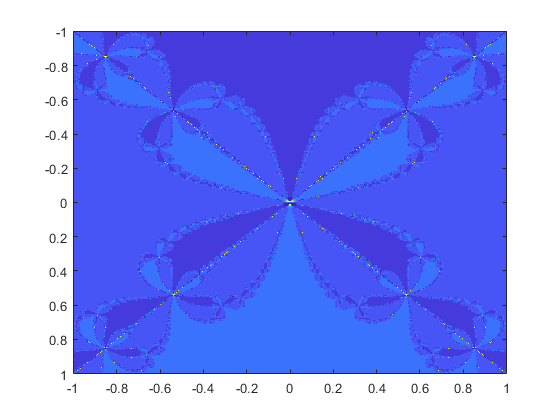

f = @(z) z.^4-1;
fd = @(z) 4*z.^3;
close all
basinNewtonf(f,fd)

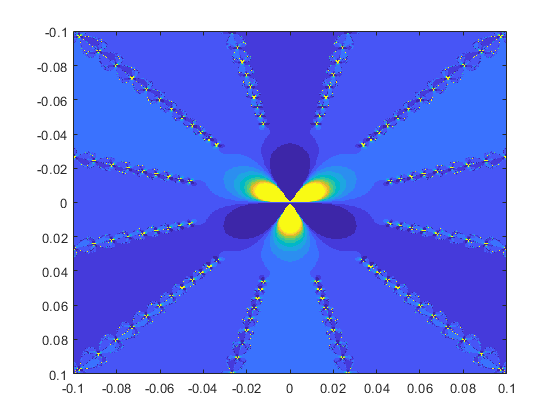

figure()
basinNewtonf(f,fd,-0.1,0.1,-0.1,0.1)